## 定义网络架构

% Generator Network
numLatentInputs = 128;
embeddingDimension = 64;
numFilters = 8;
lgMultiple = 6;
filterSize = 5;
projectionSize = [1, 2, 1024];

layersGenerator = [
    imageInputLayer([1,1,numLatentInputs],'Normalization','none','Name','in')
    projectAndReshapeLayer(projectionSize,numLatentInputs,'proj');
    concatenationLayer(3,2,'Name','cat');

    transposedConv2dLayer([1, filterSize],lgMultiple*numFilters,Stride=[1,4],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([1, filterSize],lgMultiple*numFilters,Stride=[1,4],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([1, filterSize],lgMultiple*numFilters,Stride=[1,4],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([1, filterSize],lgMultiple*numFilters,Stride=[1,4],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([1, filterSize],numInputChannels,Stride=[1,4],Cropping="same")];

lgraphGenerator = layerGraph(layersGenerator);

layers = [
    imageInputLayer([1,1],'Name','labels','Normalization','none')
    embedAndReshapeLayer(projectionSize(1:2),embeddingDimension,numClasses,'emb')];

lgraphGenerator = addLayers(lgraphGenerator,layers);
lgraphGenerator = connectLayers(lgraphGenerator,'emb','cat/in2');
dlnetGenerator = dlnetwork(lgraphGenerator);

% Discriminator Network
scale = 0.2;
dropoutProb = 0.6;
ldMultiple = 1/2;

inputSize = [lenaccelh,lenaccelw,numInputChannels];

layersDiscriminator = [
    imageInputLayer(inputSize,'Normalization','none','Name','in')
    dropoutLayer(dropoutProb)
    concatenationLayer(3,2,'Name','cat')

    convolution2dLayer([1, filterSize],ldMultiple*numFilters,Stride=[1,2],Padding="same")
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([1, filterSize],ldMultiple*numFilters,Stride=[1,4],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([1, filterSize],ldMultiple*numFilters,Stride=[1,4],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([1, filterSize],ldMultiple*numFilters,Stride=[1,4],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([1, filterSize],ldMultiple*numFilters,Stride=[1,4],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    dropoutLayer(dropoutProb)
    convolution2dLayer([1, filterSize],1,Stride=[1,4],Padding="same")];

lgraphDiscriminator = layerGraph(layersDiscriminator);

layers = [
    imageInputLayer([1,1],'Name','labels','Normalization','none')
    embedAndReshapeLayer(inputSize,embeddingDimension,numClasses,'emb')];

lgraphDiscriminator = addLayers(lgraphDiscriminator,layers);
lgraphDiscriminator = connectLayers(lgraphDiscriminator,'emb','cat/in2');
dlnetDiscriminator = dlnetwork(lgraphDiscriminator);

## Specify Training Options

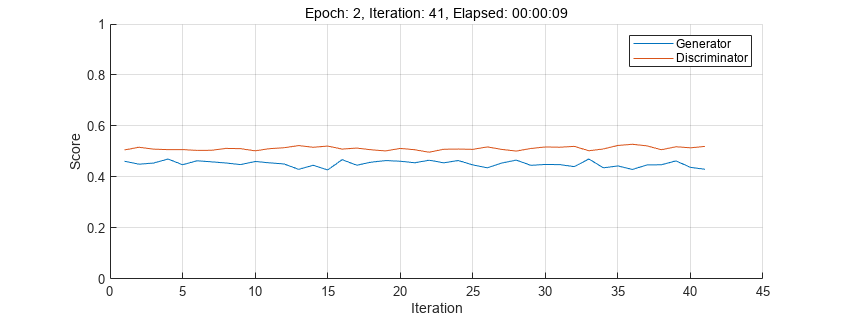

params.numLatentInputs = numLatentInputs;
params.numClasses = numClasses;
params.sizeData = [inputSize length(labeltra)];
params.numEpochs = 500;
params.miniBatchSize = 256;
params.executionEnvironment = "gpu";
% Specify the options for Adam optimizer
params.learnRate = 0.0001;
params.gradientDecayFactor = 0.5;
params.squaredGradientDecayFactor = 0.999;
% 开始训练
[dlnetGenerator,dlnetDiscriminator,scoreG,scoreD] = trainGAN(dlnetGenerator,dlnetDiscriminator,datastra,labeltra,params);

save("GDCNN_AWGN08_WSDT111.mat")